# SMC

Diseño y simulación de un controlador de modo deslizante para un modelo simplificado de un motor dc. 

lambda1 = 0; lambda2 = 0; delta_x1 = 0; 

Propiedades del motor

addpath("data/"); 
addpath("controllers/SMC"); 

load("TF.mat")
load("observer.mat"); 

% Files 

SIME_FILE = "controllers/SMC/design/smc.slx"; 

## Cálculo del beta

beta=90

beta = 90

MAX_PWM=beta

MAX_PWM = 90

a=1

a = 1

delta=30*pi/180

delta = 0.5236

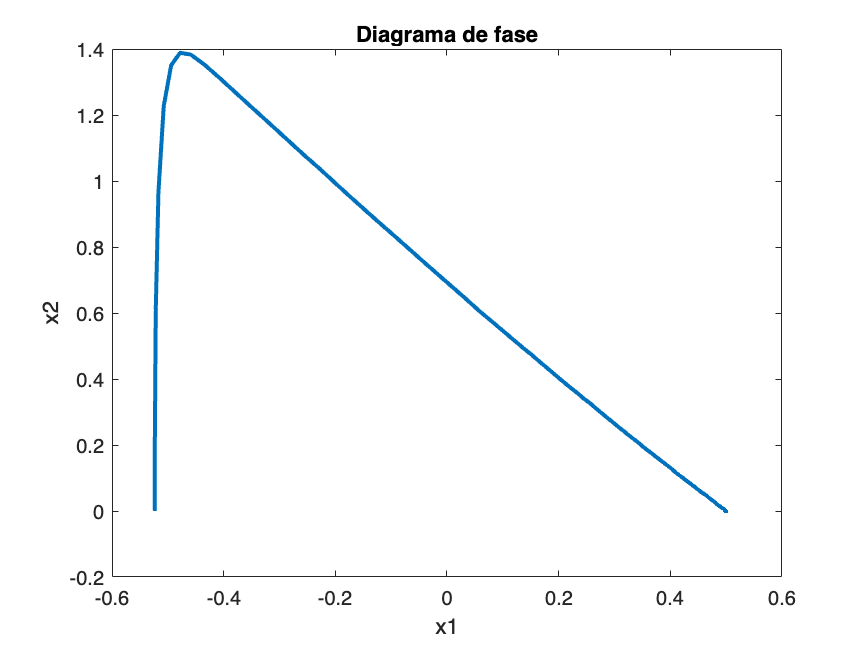


results = sim(SIME_FILE);

t = results.tout; % tiempo de simulación

% Estados del sistema
x1 = results.errorTheta.Data;
x2 = results.Omega.Data;

figure(); 


plot(x1, x2, '-', 'LineWidth',2); hold on; 
title("Diagrama de fase"); 
xlabel("x1"); ylabel("x2"); 

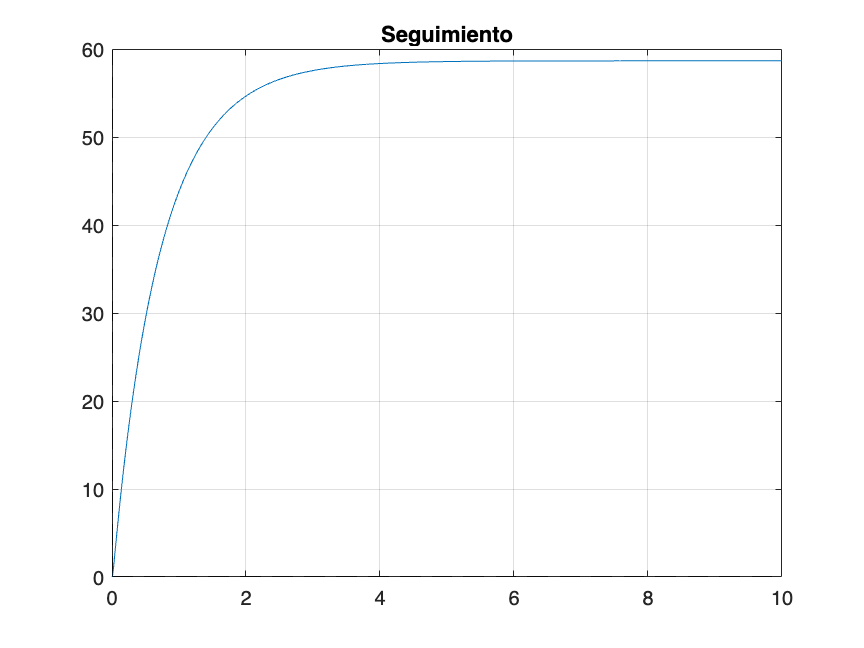


figure()

plot(t,results.Theta.Data*180/pi)
xline(0, 'k--'); yline(0, 'k--'); 
title("Seguimiento");
grid on; 

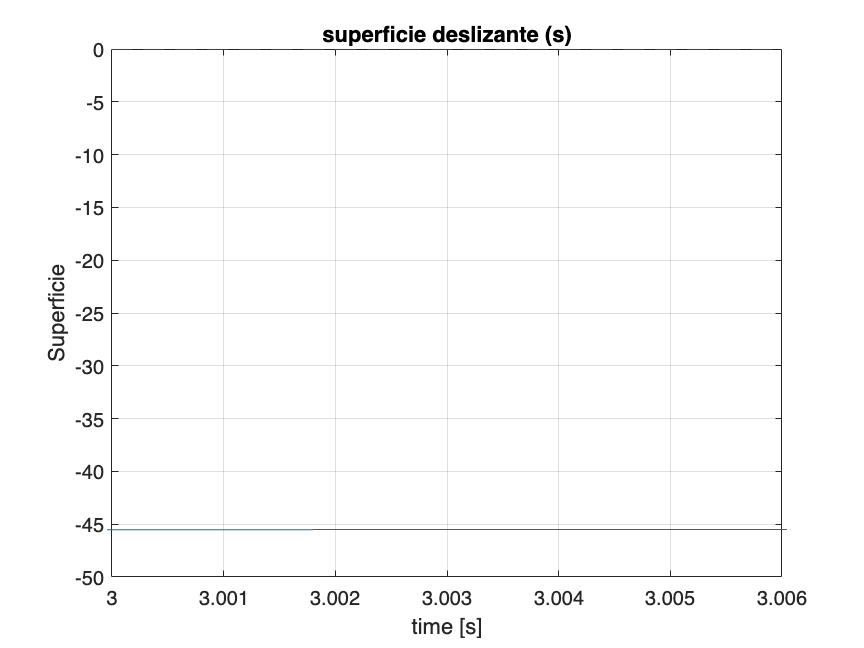


figure()

plot(t, results.U.Data); hold on; 
yline(0, 'r--'); 
title("superficie deslizante (s)")
xlabel("time [s]"); 
ylabel("Superficie"); 
grid on; 
hold off; 


xlim([3 3.006])

% condiciones iniciales 
x10 = 0; 
x20 = 0; 

delta_x1 = 0; %-pi/6; 

results = sim(SIME_FILE); 

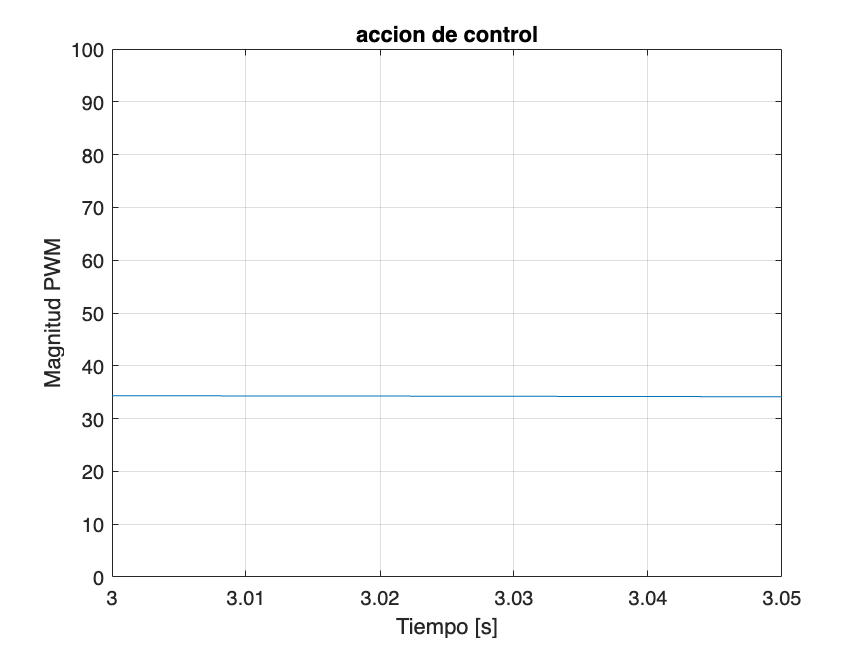



t = results.tout; % tiempo de simulación    

% Estados del sistema
x1 = results.Theta.Data;
x2 = results.Omega.Data;

% Accion de control 
figure()
u = results.U.Data; 
plot(t, u + beta);
title("accion de control");
ylabel("Magnitud PWM"); xlabel("Tiempo [s]"); 
axis([ 3 3.05 0 100]); grid on; 

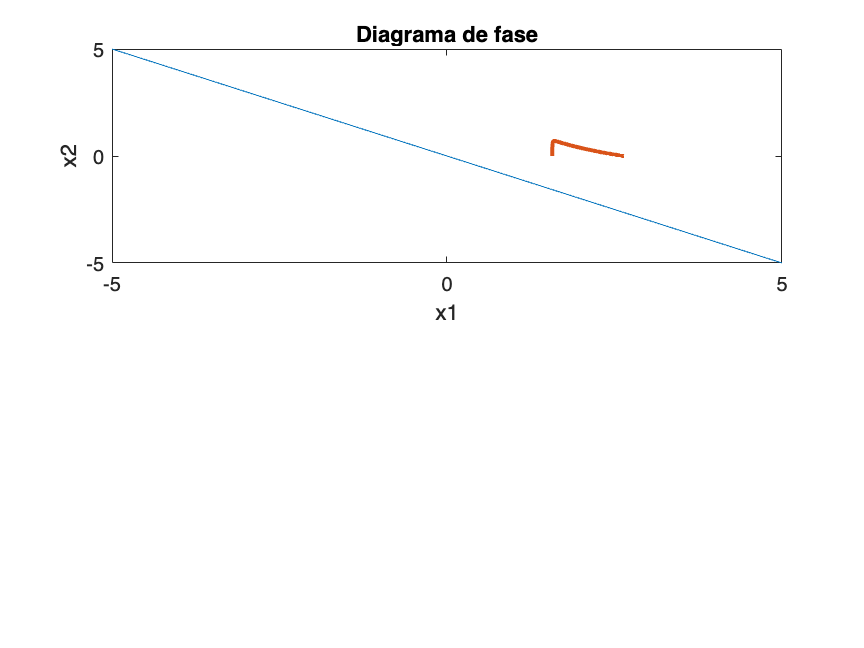

Error using matlab.graphics.axis.Axes/set
Value must be a 1x2 vector of numeric type in which the second element is greater than the first element or is Inf.

Error in axis>LocSetLimits (line 293)
    set(ax,...

Error in axis (line 114)
                LocSetLimits(ax(j),cur_arg,nam




figure(); 
subplot(2, 1, 1);

% superficie deslizante 
x = -5:0.01:5; 
plot(x, -a*x);  hold on; 

plot(x1, x2, '-', 'LineWidth',2); hold on; 
title("Diagrama de fase"); 
xlabel("x1"); ylabel("x2"); 
axis([-abs(x10) * 1.2, abs(x10) * 1.2, -4, 4]); 

scatter(x10 - delta_x1, x20, 'r*'); 



xline(0, 'k--'); yline(0, 'k--'); 
grid on; 

subplot(2, 1, 2);

% Superficie deslizante 
s = results.s.Data; 


plot(t, s); hold on; 
yline(0, 'r--'); 
title("superficie deslizante (s)")
xlabel("time [s]"); 
ylabel("superficie"); 
grid on; 
hold off; 


figure(); 
plot(t, x1, t, x2)
yline(delta_x1)
hold off; legend("\theta", "\omega")

## Control equivalente

La accion complementaria se define con el termino de perturbaicion / incertidumbre


$$\delta \;\left(x\right)=a\;\left\lbrack 1-\frac{g\left(x\right)}{\hat{g\;} \left(x\right)}\right\rbrack x_2 +h\left(x\right)\;\ldotp \frac{g\left(x\right)}{\hat{\;g} \left(x\right)}\hat{\;h} \left(x\right)$$


Definimos el modelo afín del sistema con 


$$g\left(x\right)=\frac{d_1 }{I}$$



$$h\left(x\right)=\frac{W_{\textrm{cp}} \;d_2 -W_m \;d_1 -W_b \;e}{I}\;\sin \left(x_1 \right)-\frac{\;\mu \;}{I}x_2$$
  

delta_x1 = 1.2 / 1.5
delta_x2 = a * (1 - 1.2 / 1.5) + 0.01

x1_max = 5; 
x2_max = 1; 

rho = delta_x1 * x1_max + delta_x2 * x2_max



## Almacenamiento de informacion

Guardamos unicamente las constantes beta y a para el diseño del SMC en la misma ruta que la carpeta de SMC. 

disp("Valores calculados")
disp("  -a:" + num2str(a)); 
disp("  -beta:" + num2str(beta)); 

% Guardar los datos 
save("controllers/SMC/SMC.mat", "a", "beta");